% Housekeeping
clear
clc
close all


% Define initial parameters
b = 89; % Number of angle tested
a = 1;  % Start angle
phi = 0.6;
a1 = zeros(1, b);
a2 = zeros(1, b);
R = zeros(1, b);

% Test
for i = 1 : b

    a1(i) = a * pi / 180; % Define a1

    a2(i) = a1(i); % Define a2' by V2'/V1'

    if (phi / (cos(a1(i) * sqrt(phi ^ 2 + (1 - phi * tan(a2(i))) ^ 2)))) <= 0.72 % Test a2' by V3 /V2

        a2(i) = a2(i);

    else

        a2(i) = 0;

    end

    R(i) = tan(a1(i)) + tan(a2(i)); % Calculate results

    a = a + 1; % Increase angle by step
end

% Convert to degree
a1 = a1 .* 180 ./ pi;
a2 = a2 .* 180 ./ pi;


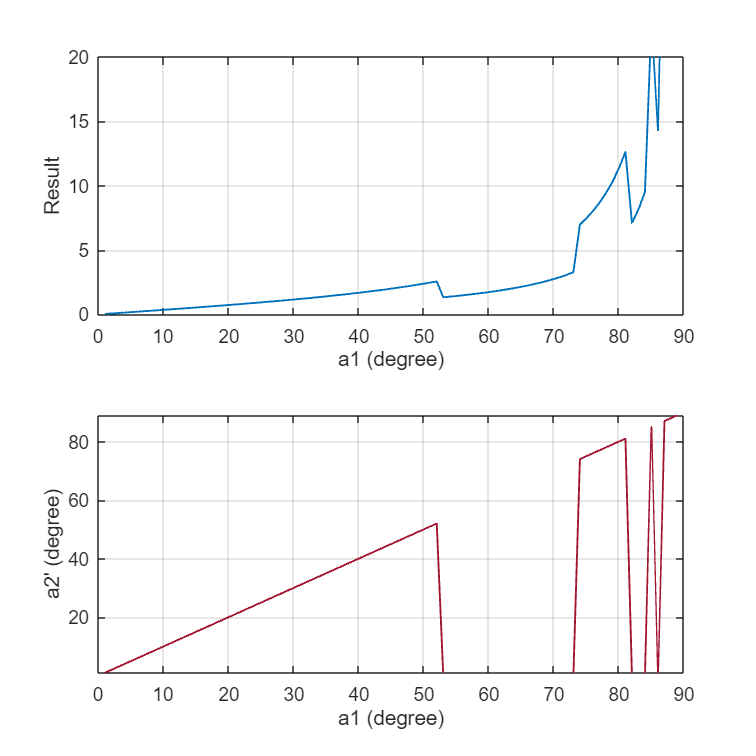

% Plot the diagram

subplot(2,1,1)
plot(a1, R, '-', 'Color', [0 0.4470 0.7410], 'LineWidth', 1);

xlabel('a1 (degree)'); 
ylabel('Result');

xlim([0 90]);
ylim([0 20]);

set(gca, 'FontSize', 10) % set the fontsize of the axis

grid on;                               % set the grid of the graph  

% Plot the diagram (as Lecture Notes P119)

subplot(2,1,2)
plot(a1, a2, '-', 'Color', [0.6350 0.0780 0.1840], 'LineWidth', 1);

xlabel('a1 (degree)'); 
ylabel("a2' (degree)");

xlim([0 90]);
ylim([1 89]);

set(gca, 'FontSize', 10) % set the fontsize of the axis

grid on;                               % set the grid of the graph
set(gcf, 'Position', [0 0 540 540]); % show plot with larger size  